% HYPERPARAMETERS
DELTA = 2.0; % Defines how much to enhance the image using the Java code (see their paper for details)
ALPHA = 0.3; % Sets how much to adjust the image based on JND (0 <= ALPHA < 1), larger = more differences at a pixel level
BRIGHTNESS_REDUCTION = 0.6; % How much to reduce the original image brightness (e.g. 0.4 = 60% reduction)
OUTPUT_FOLDER = 'output/'

OUTPUT_FOLDER = 'output/'


% Reference images (14 total)
ref_imgs = ["input/0801.jpg"; 
            "input/0802.jpg"; 
            "input/0803.jpg"; 
            "input/0806.jpg"; 
            "input/0807.jpg"; 
            "input/0808.jpg"; 
            "input/0814.jpg"; 
            "input/0823.jpg"; 
            "input/0841.jpg"; 
            "input/0873.jpg"; 
            "input/0876.jpg"
            "input/0884.jpg"; 
            "input/0887.jpg"; 
            "input/0900.jpg";
            ];

for IMG_IDX = 1:14 % Easier to iterate through a list of image names instead of manually changing the image name at each iteration
orig_img = imread(ref_imgs(IMG_IDX));
orig_img = reduce_brightness(orig_img, BRIGHTNESS_REDUCTION, 'multiply');
[~, input_filename, ext] = fileparts(ref_imgs(IMG_IDX));
enhanced_file = "tmp/" + input_filename + "_enhanced" + ext;

% Enhance the image using the Java code (based on Human Contrast Sensitivity)
system("java Contrast " + ref_imgs(IMG_IDX) + " " + enhanced_file + " " + DELTA);

% Load the enhanced image
enhanced_img = imread(enhanced_file);

% Compute brightnesses
orig_brightness = compute_brightness(orig_img);
enhanced_brightness = compute_brightness(enhanced_img);

% Display the images
imshow(orig_img);
disp(['Original brightness: ' num2str(orig_brightness)]);

imshow(enhanced_img);
disp(['Enhanced brightness: ' num2str(enhanced_brightness)]);

Reading input file. 
Dimensions3 1356 2040 
Converted the Image to Lxy notation 
Generated the Maximum Envelop 
Starting first pass. 
 Number of components is 1 
Number of hillocks is 1 
 Number of components is 289 
Number of hillocks is 1 
 Number of components is 1335 
Number of hillocks is 48 
 Number of components is 2 
Number of hillocks is 48 
 Number of components is 1 
Number of hillocks is 48 
 Number of components is 1 
Number of hillocks is 48 
 Number of components is 2 
Number of hillocks is 48 
 Number of components is 1 
Number of hillocks is 48 
 Number of components is 1 
Number of hillocks is 48 
 Number of components is 2 
Number of hillocks is 49 
 Number of components is 1 
Number of hillocks is 49 
 Number of components is 0 
Number of hillocks is 48 
 Number of components is 1 
Number of hillocks is 48 
 Number of components is 1 
Number of hillocks is 48 
 Number of components is 3 
Number of hillocks is 50 
 Number of components is 1 
Number of hillocks is 50 

Original brightness: 30.3226


Enhanced brightness: 50.0188


Reading input file. 
Dimensions3 1356 2040 
Converted the Image to Lxy notation 
Generated the Maximum Envelop 
Starting first pass. 
 Number of components is 1 
Number of hillocks is 1 
 Number of components is 1711 
Number of hillocks is 14 
 Number of components is 10 
Number of hillocks is 14 
 Number of components is 13 
Number of hillocks is 17 
 Number of components is 1 
Number of hillocks is 17 
 Number of components is 2 
Number of hillocks is 18 
 Number of components is 0 
Number of hillocks is 17 
 Number of components is 0 
Number of hillocks is 16 
 Number of components is 2 
Number of hillocks is 17 
 Number of components is 2 
Number of hillocks is 18 
 Number of components is 1 
Number of hillocks is 18 
 Number of components is 0 
Number of hillocks is 17 
 Number of components is 1 
Number of hillocks is 17 
 Number of components is 2 
Number of hillocks is 18 
 Number of components is 1 
Number of hillocks is 18 
 Number of components is 0 
Number of hillocks is 17

if enhanced_brightness < orig_brightness
    final_img = enhanced_img;
    final_brightness = compute_brightness(final_img);
else
    type = 'Yang'; 
    
    % Convert RGB to Lab color space (L = brightness, min=0, max=100)
    % We changed to Lab instead of YCbCr since converting between YCbCr and RGB
    % did not preserve the image brightness (i.e. converting the RGB image back
    % into YCbCr would result in different Y channel values).
    img_Lab = rgb2lab(enhanced_img);
    L = double(img_Lab(:,:,1));
    
    % Compute the JND thresolds at a pixel level
    jnd_Y = JND_pixel(L, type);
    
    % Visualize the JND thresholds
    % figure
    % imagesc(jnd_Y)
    % colorbar
    % saveas(gcf,'output/' + input_filename + '_jnd_raw.png')
    
    % Take the additive inverse
    jnd_Y = -1.*jnd_Y;
    
    % Compute the JND adjustment map
    stdev = std2(jnd_Y);
    jnd_Y = (jnd_Y - mean2(jnd_Y)) / stdev;
    
    jnd_min = -1*stdev;
    jnd_max = stdev;
    jnd_Y(jnd_Y < jnd_min) = jnd_min;
    jnd_Y(jnd_Y > jnd_max) = jnd_max;
    jnd_Y = (jnd_Y - jnd_min) / (jnd_max - jnd_min) * (ALPHA) + (1-ALPHA);
    
    beta = 1;
    STEP_SIZE = 0.01;
    
    % Iteratively determine how much to adjust the image
    cur_brightness = mean2(beta .* jnd_Y .* L);
    while orig_brightness < cur_brightness
        beta = beta*(1-STEP_SIZE);
        cur_brightness = mean2(beta .* jnd_Y .* L);
    end 
    
    % Visualize the JND thresholds
    % figure
    % imagesc(beta.*jnd_Y)
    % colorbar
    % saveas(gcf,'output/' + input_filename + '_jnd_adjust.png')
    
    % Use JND to reduce the image brightness to the original brightness
    Y_new = beta.* jnd_Y .* L;
    
    img_Lab(:,:,1) = Y_new;
    final_img = lab2rgb(img_Lab); % convert back to RGB
    final_brightness = compute_brightness(final_img);
    
    % Display final image
    imshow(final_img);
    disp(['Final brightness: ' num2str(final_brightness)]);
end

Final brightness: 30.1279


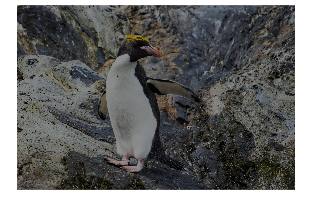

% Uniform adjustment (as a baseline)
cur_img = enhanced_img;
cur_brightness = enhanced_brightness;

if cur_brightness > orig_brightness
    factor = orig_brightness / cur_brightness;
    cur_img = reduce_brightness(cur_img, factor, 'multiply');
    cur_brightness = compute_brightness(cur_img);
end

% Compute final image brightness
uniform_img = cur_img;
uniform_brightness = compute_brightness(uniform_img);

% Display uniform adjusted image
imshow(uniform_img);

disp(['Uniform brightness: ' num2str(uniform_brightness)]);

Uniform brightness: 30.3223


% Save the images to an output directory
imwrite(orig_img, [OUTPUT_FOLDER + input_filename + '_' + num2str(orig_brightness) + '_input.jpg'], 'jpg');
imwrite(final_img, [OUTPUT_FOLDER + input_filename + '_' + num2str(final_brightness) + '_output.jpg'], 'jpg');
% imwrite(uniform_img, [OUTPUT_FOLDER + input_filename + '_' + num2str(uniform_brightness) + '_uniform.jpg'], 'jpg');
end
delete('tmp/*'); % Delete intermediate output from Java code